# **Parallel Computing Applications in Finance**

*The following post is from* [*Jue Liu*](https://www.linkedin.com/in/jue-l/)*, *[*Lixue Cheng*](https://www.linkedin.com/in/charlottecheng0501/)* from Columbia University and *[*Yuchen Dong*](https://www.linkedin.com/in/yuchen-dong-48061582/)*, *[*Weinan Chen*](https://www.linkedin.com/in/weinan-chen-30bb3b50/)* from MathWorks.*

## **Background**

Monte Carlo simulation is a widely used computational algorithm in finance for modeling the behavior of asset prices and estimating the value of financial derivatives, such as options. The method leverages the power of random sampling to understand the impact of risk and uncertainty in financial models. By simulating the various paths an asset price might take, Monte Carlo simulation can provide insights into the potential future outcomes of investments.

In this live script, we will employ Monte Carlo simulation to estimate the price of a European call option. We will generate multiple simulated paths for the underlying asset price, calculate the payoff for each path, and then average these payoffs to estimate the option's price. Additionally, we will compare the Monte Carlo estimated price with the theoretical price derived from the Black-Scholes formula to evaluate the accuracy and effectiveness of the Monte Carlo method. 

This approach not only demonstrates the practical application of Monte Carlo simulation in finance but also highlights its robustness in handling complex financial instruments and market uncertainties by using MATLAB and Python.

All experiments are running with the connection to parallel pool with 4 workers. We also test the results in different configurations. 

% Clear environment
clear; clc; close all;

## Monte Carlo Simulation Algorithm

Monte Carlo simulation is a numerical method used in option pricing to approximate the value of an option by simulating multiple possible future paths of the underlying asset's price. 

#### **Initialization of Parameters **

We start by initializing the option parameters for the simulation:

- $S_0$: initial stock price

- $K$: strike price

- $r$: risk-free interest rate

- $\sigma$: volatility

- $T$: time to maturity

- $N$: number of Monte Carlo Simulation paths

- $M$: number of time steps

- $dt$: times increments, which is equal to $\frac{T}{M}$.

#### **Time Discretization and Price Simulation**

Assume the stock returns satisfying the geometric Brownian motion. Then the stock price is simulated using the explicit Euler method:


$$S_{t+1} =S_t \;+\;rS_t \textrm{dt}\;+\sigma S_t \sqrt{\textrm{dt}}Z$$


where $Z$ is random numbles sampled from a standard normal distribution. 

#### **Option Payoff Calculation**

For each path, the option payoff is calculated as follows:


$$\textrm{Payoff}=\max \left(S_t -K,\;0\right)$$


All the path payoffs are discounted and averaged to obtain the simulated price of a European call option:


$$\textrm{MC}\_\textrm{Price}=e^{-\textrm{rT}} E\left(\textrm{Payoff}\right)$$


#### **Black-Scholes Formula**

The Black-Scholes formula for calculating the price of a European call option is given by:


$$C=S_0 N\left(d_1 \right)-Ke^{-\textrm{rT}} N\left(d_2 \right)$$


where

$d_1 =\frac{\ln \left(\frac{S_0 }{K}\right)+\left(r+\frac{\sigma^2 }{2}\right)T}{\sigma \sqrt{T}}$, $d_2=d_1-\sigma\sqrt{T}$.

Here, $N(d)$ represents the cumulative distribution function of the standard normal distribution. In the following part, we use the MATLAB built-in function [blsprice](https://www.mathworks.com/help/finance/blsprice.html?s_tid=srchtitle_site_search_1_blsprice) to calculate the theoretical price.

## Monte Carlo Simulations in MATLAB

In this section, we used the [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html) to accelerate the computational speed. Define the random seed to replicate the experiment results.

rng(100, 'twister');

Set up the parameters for a European call option, including the initial stock price, strike price etc. To analyze the runtime and computational cost, we set up different numbers of simulation paths from $1000$ to $10^7$.

S0 = 100;  % Initial stock price
K = 100;  % Strike price
r = 0.05;  % Risk-free interest rate
sigma = 0.2;  % Annualized volatility
T = 1;  % Time to maturity in year
M = 1000; 
dt = T/M;  % Time step
Ns = [1000, 5000, 10000, 50000, 100000, 500000, 1000000, 5000000, 10000000];  % Simulation path

% Results table
MATLAB_Results = table(Ns', zeros(length(Ns),1), zeros(length(Ns),1), zeros(length(Ns),1), zeros(length(Ns),1), zeros(length(Ns),1), ...
    'VariableNames', {'N', 'MC_Price', 'BS_Price', 'Error', 'NonParallel_Time', 'Parallel_Time'});

To avoid waiting for the Monte Carlo simulation, load the calculating results for the example by setting `doComputing` flag to `false`.

doComputing = false;

if doComputing
    % Check parallel pool
    if isempty(gcp('nocreate'))
        parpool;
    end
    % Perform simulaions for each path
    for index = 1:length(Ns)
        N = Ns(index);

        % Calculate option price (blsprice benchmark)
        [CallPrice, ~] = blsprice(S0, K, r, T, sigma);

        % Monte Carlo simulation (Non-parallel)
        tic;
        payoffsNonParallel = zeros(N,1);
        for i = 1:N
            S = S0;
            for j = 1:M
                Z = randn;
                S = S + r*S*dt + sigma*S*sqrt(dt)*Z;  % Explicit form
            end
            payoffsNonParallel(i) = max(S - K, 0);
        end
        MC_Price = exp(-r * T) * mean(payoffsNonParallel);
        MATLAB_Results.NonParallel_Time(index) = toc;

        % Monte Carlo simulation (Parallel)
        tic;
        payoffsParallel = zeros(N,1);
        parfor i = 1:N
            S = S0;
            for j = 1:M
                Z = randn;
                S = S + r*S*dt + sigma*S*sqrt(dt)*Z;
            end
            payoffsParallel(i) = max(S - K, 0);
        end
        MATLAB_Results.Parallel_Time(index) = toc;

        % Record results
        MATLAB_Results.MC_Price(index) = MC_Price;
        MATLAB_Results.BS_Price(index) = CallPrice;
        MATLAB_Results.Error(index) = abs(CallPrice - MC_Price);
    end

    % Display results
    disp(MATLAB_Results);
else
    load('MATLAB_Results.mat');
    disp(MATLAB_Results);
end

      N      MC_Price    BS_Price      Error      NonParallel_Time    Parallel_Time
    _____    ________    ________    _________    ________________    _____________

     1000     10.257      10.451        0.1933         0.0279           0.038583   
     5000     10.612      10.451       0.16157        0.13381            0.10113   
    10000      10.42      10.451      0.030647        0.24912            0.18489   
    50000     10.456      10.451     0.0053744         1.2423            0.78445   
    1e+05     10.376      10.451      0.074189         2.5257             1.5902   
    5e+05     10.466      10.451      0.015656          12.53              8.097   
    1e+06     10.444      10.451     0.0064848         25.564             18.213   
    5e+06     10.458      10.451     0.

## Monte Carlo Simulations in Python

In this part, we applied the Monte Carlo Simulations in Python. There are several packages used in parallel computing, such as multiprocessing, joblib. In this example, we use the `multiprocessing` package. 

doComputingPython = false;

if doComputingPython
    pyenv(ExecutionMode="OutOfProcess");
    temp = pyrunfile("monte_carlo_multiprocessing.py","results_df");
    Python_Results = table(temp);
    terminate(pyenv)
else
    load('Python_Results.mat');
    disp(Python_Results);
end

       N       MC_Price    BS_Price      Error      NonParallel_Time    Parallel_Time
    _______    ________    ________    _________    ________________    _____________

       1000     11.116      10.451       0.66589         2.2647              6.99    
       5000     10.885      10.451       0.43421         11.235            3.3016    
      10000     10.645      10.451       0.19397         18.926            6.0126    
      50000     10.458      10.451     0.0077089         96.737            32.767    
     100000      10.46      10.451     0.0097258         214.15            90.478    
     500000     10.433      10.451       0.01715         1130.6            400.11    
    1000000      10.44      10.451      0.010441         2222.7            791.87    



## Computational Efficiency Analysis

The runtime comparison between MATLAB and Python for both non-parallel and parallel implementations across different numbers of simulation paths reveals several key insights:

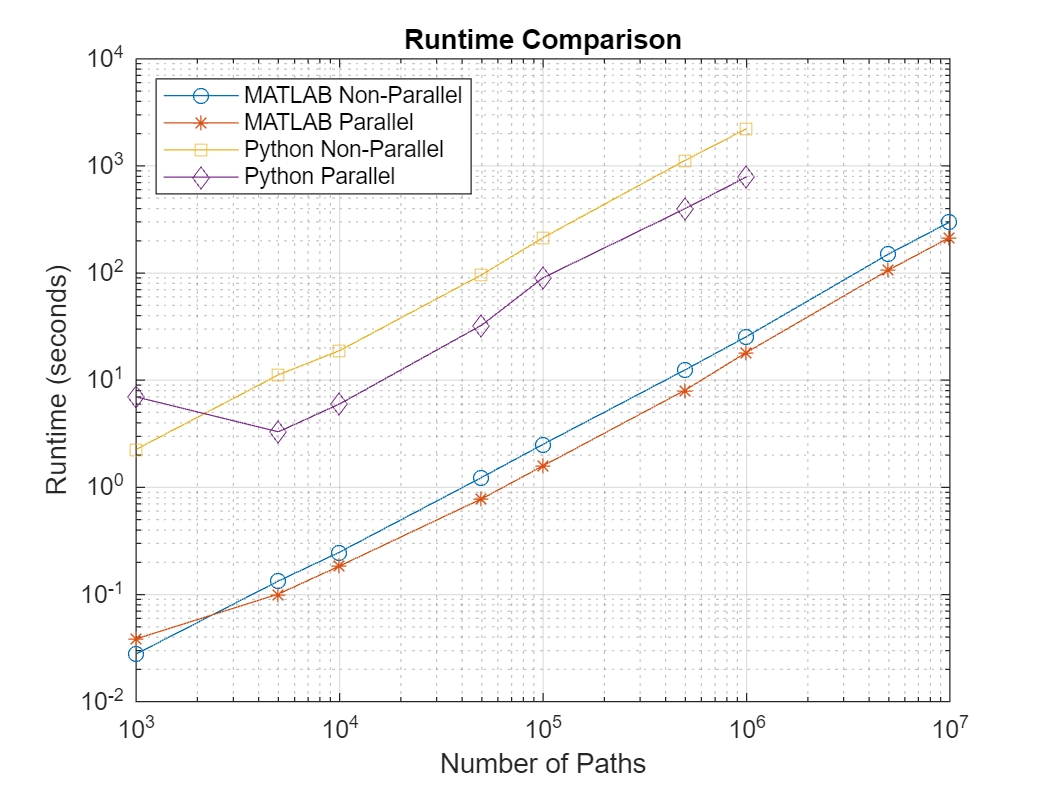

% Plot Runtime Comparison
figure;
loglog(MATLAB_Results.N, MATLAB_Results.NonParallel_Time, '-o', 'Color', [0 0.4470 0.7410], 'DisplayName', 'MATLAB Non-Parallel');
hold on;
loglog(MATLAB_Results.N, MATLAB_Results.Parallel_Time, '-*', 'Color', [0.8500 0.3250 0.0980], 'DisplayName', 'MATLAB Parallel');
loglog(Python_Results.N, Python_Results.NonParallel_Time, '-s', 'Color', [0.9290 0.6940 0.1250], 'DisplayName', 'Python Non-Parallel');
loglog(Python_Results.N, Python_Results.Parallel_Time, '-d', 'Color', [0.4940 0.1840 0.5560], 'DisplayName', 'Python Parallel');
xlabel('Number of Paths');
ylabel('Runtime (seconds)');
title('Runtime Comparison');
legend('show','Location','northwest');
grid on;
hold off

Parallel v.s. Non-parallel: 

Both MATLAB and Python show faster performance with parallel computation compared to non-parallel computation. MATLAB's parallel implementation consistently **outperforms** Python's across all path counts. This performance gap becomes particularly significant as the number of paths increases.

Scalability:

MATLAB outperforms Python in both parallel and non-parallel computations. Particularly in high-iteration simulations, MATLAB's parallel implementation is significantly faster. 

Initialization Overhead:

Both implementations display an initial overhead for smaller path counts, likely attributable to setup and initialization costs. This effect is more pronounced in the performance disparity observed at lower path counts.

Numerical Stability:

Both MATLAB and Python implementations demonstrate a general trend of decreasing absolute error as the number of simulation paths increases, consistent with the expected convergence behavior of Monte Carlo methods. MATLAB's absolute error consistently decreases with increasing path counts.

## High Performance and GPU computing

To improve the computing performance, we also worked on the vectorized version and use GPU. In this test, we used the AWS provided g5 instance that contains NVIDIA A10G machine. It has 72 streaming processors and 24 GB of memory. Below are the performance comparison using $10^6$ simulation paths. The Python GPU computing is done with PyTorch 2.4 and PyTorch-CUDA version 12.1. All calculations are performed at defualt double precision. 

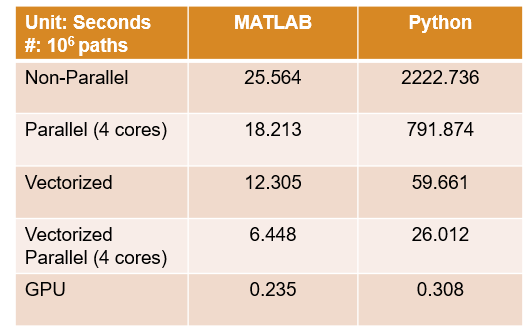

## Explanation

MATLAB uses **Just-in-Time (JIT) compilation**, optimizing code on the fly for faster execution. It is efficient to convert the code into **matrix operations** in both MATLAB and Python. MATLAB is designed for efficient matrix and array manipulations. At the initial stage, significant startup overhead due to the need to start multiple workers, and assign tasks. For the error analysis, Monte Carlo simulations rely on random number generation, causing fluctuations in error even as the sample size increases.

## **Conclusions**

Overall, Monte Carlo simulation is an invaluable technique for pricing options, providing reliable estimates through the simulation of numerous asset price paths. Our comparative study highlights MATLAB's superior performance in both non-parallel and parallel computations, thanks to its optimized numerical libraries and efficient parallel computing toolbox. This advantage is evident in its smoother error reduction and consistent accuracy. MATLAB's advanced features, including its robust parallel processing capabilities and optimized matrix operations, make it the preferred choice for complex financial modeling tasks.

## Resources to Learn More

- [Reduce Time to Results with MATLAB Using Parallel Computating](https://www.mathworks.com/videos/reduce-time-to-results-with-matlab-using-parallel-computing-1691992378869.html?s_tid=srchtitle_site_search_1_Parallel_Time)